# LiDARDRONE

# Drone Control with pid dynamics

MRK 1.6

17/5 integrated the imu in the simulation and rrt based on lidar measurement

25/5 fixed and cleaned the code

29/5 RRT driven oriented

25/6 Added the comunication between drones and the sharing maps

26/6 Fixed the colors of plots

________________________________

clc;
clear;
clear all;
clf;

tic;

% Add the path of the functions
addpath('C:\Users\matte\Documents\UNI\IDS\gabri_reborn\functions');
addpath('C:\Users\matte\Documents\UNI\IDS\gabri_reborn\pictures');

#### Map definition and obstacles plot

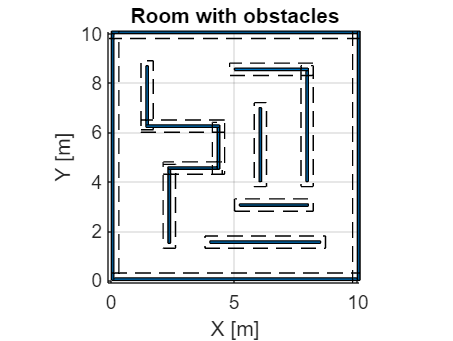

% Define the sizes of the map
x_map_size = 10;    % [m]
y_map_size = 10;    % [m]

% Define the map with its walls
[obstacles, inflated_obstacles] = map_definition;

%Plot
figure(1);
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);

## DRONE SPECS Initialization

Define all the specs for each drone 

% Number of drones to put in the simulation
n = 3;
n_droni = n;

% Define a new struct to save all the data for all the drones
Drone = struct(); 

% For each drone compute the following
for i = 1:n

    % Define drone specifications such as name and color
    drone_name = ['Drone_' num2str(i)];
    Drone.(drone_name).color = color(i); %Drone and scanning color CAMBIEREI METTENDO UN VETTORE DI COLORE: A SECONDA DEL NUMERO STAMPA DIRETTAMENTE CON QUEL COLORE

    %RRT starting point position (RANDOM POINT)
    Drone.(drone_name).map = [rand() * x_map_size, rand() * y_map_size]; % first corresppond to the starting_point
    while isInObstacle(Drone.(drone_name).map,inflated_obstacles) == true
        % If the random starting point position is inside obstacles,
        % calculate another point
        Drone.(drone_name).map =[rand() * x_map_size, rand() * y_map_size];
    end

    Drone.(drone_name).RRT.step_size = 0.3; % [m]distance between each step during the RRT exploration algorithm
    Drone.(drone_name).RRT.n_iterations = 10;   % [-] number of iteration for each RRT tree
    Drone.(drone_name).RRT.inflate = 0.7;   % [m] inflation of obstacles 
    Drone.(drone_name).RRT.fov_drone = 2;   % field of view of the single drone to buikld the rrt
    Drone.(drone_name).RRT.parent_indices = 0;  % Indices numbers to link the points of the trees
    Drone.(drone_name).RRT.imu_noise = 0.1; % [m] max amplitude of the noise of the accelerometer

    Drone.(drone_name).PID.Kp = 0.6; % component proporzionale
    Drone.(drone_name).PID.Ki = 0.02; % componente integrale
    Drone.(drone_name).PID.Kd = 0.9; % componente derivativa
    Drone.(drone_name).PID.initial_vel = [0; 0]; % [m/s] initial velocity in the RRT
    Drone.(drone_name).PID.max_speed = [1; 1]; % [m/s] max speed
    Drone.(drone_name).PID.max_acc = [1;1]; % [m/s] max acc

    %Lidar parameters specifications
    Drone.(drone_name).Lidar.lidar_angles = linspace(0, 360, 100);  % Number of rays [-]
    Drone.(drone_name).Lidar.scanning_lines = 100;  % resolution in terms of number of rays
    Drone.(drone_name).Lidar.max_range = 3;         % Maximum length measurement [m]
    Drone.(drone_name).Lidar.lidar_dist_res = 0.0002; % Distance measurement resolution 0.002 [m]
    Drone.(drone_name).Lidar.Drone_rel_position = [0,0]; % Initial relative position
    Drone.(drone_name).Lidar.scan_points = [];  % Relative positions of the drone during its exploration
    Drone.(drone_name).Lidar.scan_points_new = []; %for fusion with same drone scans
    Drone.(drone_name).Lidar.scan_dist_new = []; %for fusion with same drone scans
    Drone.(drone_name).Lidar.profile = [];
    Drone.(drone_name).Lidar.peaks = [];

end

nearest_points_tresshold = 0.05; %0.05
filtering_landmarks_threshold = 5;
Communication_matrix = zeros(n,n);
com_index_1 = 1;
com_index_2 = 1;
communication_tresshold = 0.7;
time_to_comunicate = 400; %[time_step]

## INITIALIZE DRONES SIMULATION (STEP 0)

% Simulation setup
SetUp.Dt = 0.1; % [s]
setUp.MaxTime = 100; % [s]
count = 1; %n_iterations

%Step 0 simulation
for i = 1:n
    drone_name = ['Drone_' num2str(i)];

    %first scan
    [~,~, Drone.(drone_name).Lidar.scan_points, Drone.(drone_name).Lidar.scan_dist] = Lidar_scan(obstacles, Drone.(drone_name).map, Drone.(drone_name).Lidar.lidar_angles, Drone.(drone_name).Lidar.max_range, Drone.(drone_name).Lidar.lidar_dist_res);
    Drone.(drone_name).count_pos = 1;
    %creating obstacles from scan
    Drone.(drone_name).Lidar.obstacles_lidar = lidar_data_to_obstacles(Drone.(drone_name).Lidar.scan_points,Drone.(drone_name).RRT.inflate);
    
    
    %creating rrt treee
    [Drone.(drone_name).RRT.rrt_tree, Drone.(drone_name).RRT.parent_indices] = RRT_DRONE(Drone.(drone_name).RRT.step_size, Drone.(drone_name).RRT.n_iterations, Drone.(drone_name).RRT.fov_drone, Drone.(drone_name).Lidar.scan_points, Drone.(drone_name).RRT.inflate);
    Drone.(drone_name).RRT.farest = [0; 0];
    Drone.(drone_name).RRT.dist_farest = 0;
    for k=2:length(Drone.(drone_name).RRT.rrt_tree)
        %Drone.(drone_name).RRT.temp_point = Drone.(drone_name).RRT.rrt_tree(k, :);
        if norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :)) > Drone.(drone_name).RRT.dist_farest
            Drone.(drone_name).RRT.dist_farest = norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :));
            Drone.(drone_name).RRT.farest = Drone.(drone_name).RRT.rrt_tree(k, :);
        end
    end
    Drone.(drone_name).RRT.correspondence = ismember(Drone.(drone_name).RRT.rrt_tree, Drone.(drone_name).RRT.farest, 'rows');
    Drone.(drone_name).RRT.index = find(all(Drone.(drone_name).RRT.correspondence, 2));
    Drone.(drone_name).RRT.points_rrt = [];
    while Drone.(drone_name).RRT.index ~= 0
        Drone.(drone_name).RRT.points_rrt = [Drone.(drone_name).RRT.rrt_tree(Drone.(drone_name).RRT.index, :); Drone.(drone_name).RRT.points_rrt];
        Drone.(drone_name).RRT.index = Drone.(drone_name).RRT.parent_indices(Drone.(drone_name).RRT.index);
    end

    %creating intermediates goals and final goal
    Drone.(drone_name).RRT.points = Drone.(drone_name).RRT.points_rrt';
    Drone.(drone_name).RRT.check_point_index = 2;
    Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:, Drone.(drone_name).RRT.check_point_index);

    % Initializing PID

    % Error variables
    Drone.(drone_name).PID.error_sum=0;
    Drone.(drone_name).PID.previous_error = 0;

    % Space and velocity variables
    Drone.(drone_name).RRT.initial_vel = [0; 0];
    Drone.(drone_name).RRT.positions = []; % position register
    Drone.(drone_name).RRT.reached_goal(1,1) = Drone.(drone_name).map(1,1);
    Drone.(drone_name).RRT.reached_goal(1,2) = Drone.(drone_name).map(1,2);
    Drone.(drone_name).RRT.all_positions = [Drone.(drone_name).map(1,1),Drone.(drone_name).map(1,2)]; % all pose momorized in abs terms
    
    Drone.(drone_name).RRT.pos = [0;0]; %Drone.(drone_name).RRT.points(:, 1);
    Drone.(drone_name).RRT.vel = Drone.(drone_name).PID.initial_vel;
    
   % Proximity threshold to validate if a point has been reached
    
    proximity_threshold = 0.1;
    Drone.(drone_name).timer = 1;
    Drone.(drone_name).comm_flag = 0;

    

end

## FULL ALL DRONES SIMULATION

% Make the evaulation of each drone planning, control, decision, sharing at
% each time step


for t=0:SetUp.Dt:setUp.MaxTime
    count = count + 1;
    
    for i = 1:n

        drone_name = ['Drone_' num2str(i)];

        % PID control to move the drone
        % Check actual and target position to set up the controller
        Drone.(drone_name).PID.error_pos = Drone.(drone_name).RRT.final_pos - Drone.(drone_name).RRT.pos;
            
        % Proportional component
        Drone.(drone_name).PID.control_p = Drone.(drone_name).PID.Kp * Drone.(drone_name).PID.error_pos;

        % Integral component
        Drone.(drone_name).PID.error_sum = Drone.(drone_name).PID.error_sum + Drone.(drone_name).PID.error_pos * SetUp.Dt;
        Drone.(drone_name).PID.control_i = Drone.(drone_name).PID.Ki * Drone.(drone_name).PID.error_sum;

        % Derivative component
        Drone.(drone_name).PID.derivative = (Drone.(drone_name).PID.error_pos - Drone.(drone_name).PID.previous_error) / SetUp.Dt;
        Drone.(drone_name).PID.control_d = Drone.(drone_name).PID.Kd * Drone.(drone_name).PID.derivative;
        
        % Speed saturation
        Drone.(drone_name).PID.control_d = min(max(Drone.(drone_name).PID.control_d, -Drone.(drone_name).PID.max_speed), Drone.(drone_name).PID.max_speed);

        % Final limited acceleration control
        Drone.(drone_name).PID.control = Drone.(drone_name).PID.control_p + Drone.(drone_name).PID.control_i + Drone.(drone_name).PID.control_d;
        Drone.(drone_name).PID.control = min(max(Drone.(drone_name).PID.control, -Drone.(drone_name).PID.max_acc), Drone.(drone_name).PID.max_acc);
        
        % IMU noise added
        Drone.(drone_name).PID.control = Drone.(drone_name).PID.control + Drone.(drone_name).RRT.imu_noise * randn(2, 1);

        % Speed and position update
        Drone.(drone_name).RRT.vel = Drone.(drone_name).RRT.vel + Drone.(drone_name).PID.control * SetUp.Dt;
        Drone.(drone_name).RRT.pos = Drone.(drone_name).RRT.pos + Drone.(drone_name).RRT.vel * SetUp.Dt;

        % Pose memorization
        Drone.(drone_name).RRT.positions = [Drone.(drone_name).RRT.positions, Drone.(drone_name).RRT.pos];
        
        Drone.(drone_name).RRT.reached_goal(count,1) = Drone.(drone_name).map(Drone.(drone_name).count_pos,1);
        Drone.(drone_name).RRT.reached_goal(count,2) = Drone.(drone_name).map(Drone.(drone_name).count_pos,2); 
        Drone.(drone_name).RRT.all_positions(count,1) = Drone.(drone_name).RRT.reached_goal(count,1) + Drone.(drone_name).RRT.pos(1,1);
        Drone.(drone_name).RRT.all_positions(count,2) = Drone.(drone_name).RRT.reached_goal(count,2) + Drone.(drone_name).RRT.pos(2,1);
        
        % Error update
        Drone.(drone_name).PID.previous_error = Drone.(drone_name).PID.error_pos;

        %------------------------------------------------------------------------------------------------------------%

        % From now on a series of if to check and control the planning
        % steps of the drone in the RRT exploration point
        
        %  Check if a general intermediate checkpoint position of the RRT tree is reached 
        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.final_pos) <= proximity_threshold && Drone.(drone_name).RRT.check_point_index < length(Drone.(drone_name).RRT.points)
            % aggiungere punto check point approx
            Drone.(drone_name).RRT.check_point_index = Drone.(drone_name).RRT.check_point_index +1;
            Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:,Drone.(drone_name).RRT.check_point_index); 

        end

        % Check if the final point of the local RRT tree is reached
        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.points(:,length(Drone.(drone_name).RRT.points))) <= proximity_threshold
            
            % Update of position index saved in the map
            Drone.(drone_name).count_pos = Drone.(drone_name).count_pos +1; 

            % Save the reached position in relative terms and use it in the
            % following RRT as the new starting point in the successive in
            % map variable
            Drone.(drone_name).map(Drone.(drone_name).count_pos,1) = Drone.(drone_name).map(Drone.(drone_name).count_pos-1,1) +  Drone.(drone_name).RRT.pos(1,1); %pos x abs
            Drone.(drone_name).map(Drone.(drone_name).count_pos,2) = Drone.(drone_name).map(Drone.(drone_name).count_pos-1,2) +  Drone.(drone_name).RRT.pos(2,1); %pos y abs
            Drone.(drone_name).map_rel(Drone.(drone_name).count_pos,1) = Drone.(drone_name).RRT.pos(1,1); %pos x rel
            Drone.(drone_name).map_rel(Drone.(drone_name).count_pos,2) = Drone.(drone_name).RRT.pos(2,1); %pos y rel
           
            % Save last speed of the drone in order to use it as the new
            % Starting velocity in the next RRT plannig step
            Drone.(drone_name).RRT.final_velocity = Drone.(drone_name).RRT.vel;

            % New scan in the reached point in order to generate the new RRT 
            [~,~, Drone.(drone_name).Lidar.scan_points_new, Drone.(drone_name).Lidar.scan_dist_new] = Lidar_scan(obstacles, Drone.(drone_name).map(Drone.(drone_name).count_pos,:), Drone.(drone_name).Lidar.lidar_angles, Drone.(drone_name).Lidar.max_range, Drone.(drone_name).Lidar.lidar_dist_res);
            
            % Fuse previous lidar points of the old map in the new just created
            map1 = Drone.(drone_name).Lidar.scan_points; % Old point clouds of drone n
            map2 = Drone.(drone_name).Lidar.scan_points_new; % New point cloud  drone n dto be fused
            pos1 = Drone.(drone_name).map(Drone.(drone_name).count_pos-1,:); % Old ground truth pose drone n
            pos2 = Drone.(drone_name).map(Drone.(drone_name).count_pos,:); % New (current) ground truth posizione drone n 
            
            % Virtual traslation (overlay) of old map (map1) on new reached point on new scanned map (map2)
            virtual_points = [map1(:,1)-Drone.(drone_name).RRT.pos(1,1),map1(:,2)-Drone.(drone_name).RRT.pos(2,1)];
            
            % Define the common points that theoretically are the same betweeen old and new scan
            soglia = 0.1;
            common_points = point_cloud_compare(virtual_points,map2,soglia);
            
            % Generate the new cumulated scanned point maps
            new_map2 = fused_map(virtual_points, common_points, map2, drone_name);

            % Initialization and saving new meshed map in the scan_points_field
            Drone.(drone_name).Lidar.scan_points = [0,0];
            Drone.(drone_name).Lidar.scan_points = new_map2;


%--------------CAPIRE COME E SE UTILIZZARE LANDMARK

            % %aggiorno landmarks
            % Res = 1;
            % index = 1;
            % 
            % %azzero vecchi landmarks
            % Drone.(drone_name).Lidar.profile = [0,0];
            % Drone.(drone_name).Lidar.peaks = [0,0];
            % 
            % while index <= size(Drone.(drone_name).Lidar.scan_points,1)
            %     if index <= Res || index > size(Drone.(drone_name).Lidar.scan_points,1) - (Res)
            %         Drone.(drone_name).Lidar.profile(index,1) = 1;
            %         Drone.(drone_name).Lidar.profile(index,2) = 0;
            %         Drone.(drone_name).Lidar.profile(index,3) = 0;
            %     else
            % 
            %     % Curvature
            %     F = [Drone.(drone_name).Lidar.scan_points(index-Res,1),Drone.(drone_name).Lidar.scan_points(index-Res,2), 0];
            %     G = [Drone.(drone_name).Lidar.scan_points(index,1),Drone.(drone_name).Lidar.scan_points(index,2), 0];
            %     H = [Drone.(drone_name).Lidar.scan_points(index+Res,1),Drone.(drone_name).Lidar.scan_points(index+Res,2), 0];
            % 
            %     f = norm(G - H);
            %     g = norm(F - H);
            %     h = norm(G - F);
            %     A = norm(cross(H - F, G - F) / 2);
            %     Drone.(drone_name).Lidar.profile(index,1) = 4 * A / (f * g * h); %curvature
            % 
            %     %PCA
            %     X = [Drone.(drone_name).Lidar.scan_points(index-Res:index+Res,1),Drone.(drone_name).Lidar.scan_points(index-Res:index+Res,2)];
            %     [Dir, score, Var] = pca(X);  
            %     Drone.(drone_name).Lidar.profile(index,2) = sqrt(Var(1)); %Var1
            %     Drone.(drone_name).Lidar.profile(index,3) = sqrt(Var(2)); %Var2
            %     end
            %     index = index+1;
            % end
            % 
            % filtering_threshold = 5;
% ------------------------------         


            % a = 1;
            % while a<=size(Drone.(drone_name).Lidar.profile,1)
            %     if Drone.(drone_name).Lidar.profile(a, 1) >= filtering_threshold 
            %         Drone.(drone_name).Lidar.peaks(a,1) = Drone.(drone_name).Lidar.profile(a, 1);
            %     else
            %         Drone.(drone_name).Lidar.peaks(a,1) = 0;
            %     end
            %     a = a+1;
            % end


            %% After all elaboration and classification, scan the enviroment
            % in the current (final) position to build the following RRT

            Drone.(drone_name).Lidar.obstacles_lidar = [];
            Drone.(drone_name).Lidar.obstacles_lidar = lidar_data_to_obstacles(Drone.(drone_name).Lidar.scan_points_new,Drone.(drone_name).RRT.inflate);
                        
            %% Build the new RRT in a driven way
            
            if length(Drone.(drone_name).map_rel)<3
                prev_points =  [Drone.(drone_name).map_rel(end, :); Drone.(drone_name).map_rel(end - 1, :); [0, 0]];
            else
                prev_points =  [Drone.(drone_name).map_rel(end, :); Drone.(drone_name).map_rel(end - 1, :); Drone.(drone_name).map_rel(end - 2, :)];
            end
            [Drone.(drone_name).RRT.rrt_tree, Drone.(drone_name).PID.parent_indices] = RRT_DRONE_DRIVEN(Drone.(drone_name).RRT.step_size,Drone.(drone_name).RRT.n_iterations, Drone.(drone_name).RRT.fov_drone, Drone.(drone_name).Lidar.scan_points_new, Drone.(drone_name).RRT.inflate, prev_points);
            
            % Identify the farest point of the tree and select it as final targhet
            Drone.(drone_name).PID.farest = [0; 0];
            Drone.(drone_name).PID.dist_farest = 0;
            for k=2:length(Drone.(drone_name).RRT.rrt_tree)
                Drone.(drone_name).PID.temp_point = Drone.(drone_name).RRT.rrt_tree(k, :);
                if norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :)) > Drone.(drone_name).PID.dist_farest
                    Drone.(drone_name).PID.dist_farest = norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :));
                    Drone.(drone_name).PID.farest = Drone.(drone_name).RRT.rrt_tree(k, :);
                end
            end
            Drone.(drone_name).PID.correspondence = ismember(Drone.(drone_name).RRT.rrt_tree, Drone.(drone_name).PID.farest, 'rows');
            Drone.(drone_name).PID.index = find(all(Drone.(drone_name).PID.correspondence, 2));
            Drone.(drone_name).RRT.points_rrt = [];

            while Drone.(drone_name).PID.index ~= 0
                Drone.(drone_name).RRT.points_rrt = [Drone.(drone_name).RRT.rrt_tree(Drone.(drone_name).PID.index, :); Drone.(drone_name).RRT.points_rrt];
                Drone.(drone_name).PID.index = Drone.(drone_name).PID.parent_indices(Drone.(drone_name).PID.index);
            end

            % Plan all the path of intermediate points
            Drone.(drone_name).RRT.points = Drone.(drone_name).RRT.points_rrt';
            Drone.(drone_name).RRT.check_point_index = 2;
            Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:,Drone.(drone_name).RRT.check_point_index);


            %% Restart the PID control of the drone initializing it

            % Error variables
            Drone.(drone_name).PID.error_sum=0;
            Drone.(drone_name).PID.previous_error = 0;
            
            % Set initial velocity as the last it has in the previous tree
            % and reset the initial position from which it starts to explore
            Drone.(drone_name).RRT.initial_vel = Drone.(drone_name).RRT.final_velocity;
            Drone.(drone_name).RRT.positions = []; % registro delle posizioni per la visualizzazione
            
            

            % Save all the pos and vel of the drone
            Drone.(drone_name).RRT.pos = [0;0]; 
            Drone.(drone_name).RRT.vel = Drone.(drone_name).PID.initial_vel;
            
            % continua finché non si raggiunge la destinazione
            
            proximity_threshold = 0.1;
            
        end

        %% Check for communication
        for com_index_1 = 1:n_droni           
            for com_index_2 = 1:n_droni
                drone_name_1 = ['Drone_' num2str(com_index_1)];
                drone_name_2 = ['Drone_' num2str(com_index_2)];
                distance = antenna(Drone.(drone_name_1).RRT.all_positions(count-1,:),Drone.(drone_name_2).RRT.all_positions(count-1,:));
                if distance <= communication_tresshold ...
                        && com_index_1 ~= com_index_2 && Communication_matrix(com_index_1,com_index_2) == 0 ...
                        && Communication_matrix(com_index_2,com_index_1) == 0 && (Drone.(drone_name_1).comm_flag ~= 1 ...
                        || Drone.(drone_name_2).comm_flag ~= 1)

                    Drone.(drone_name_1).comm_flag = 1;
                    Drone.(drone_name_2).comm_flag = 1;

                    disp(drone_name_1);
                    disp('chatted');
                    disp(drone_name_2);
                    disp('at');
                    disp(count*SetUp.Dt);
                    disp('seconds');
                    disp('------------------');

                    %Communication timer
                    Drone.(drone_name_1).timer = 1;
                    Drone.(drone_name_2).timer = 1;
                    Communication_matrix(com_index_1,com_index_2) = 1;
                    Communication_matrix(com_index_2,com_index_1) = 1;

                    % Update of position index saved in the map for both
                    % drones
                    Drone.(drone_name_1).count_pos = Drone.(drone_name_1).count_pos +1;
                    Drone.(drone_name_2).count_pos = Drone.(drone_name_2).count_pos +1;
        
                    % Save the reached position in relative terms for both
                    % drones
                    Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos,1) = Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos-1,1) +  Drone.(drone_name_1).RRT.pos(1,1); %pos x abs
                    Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos,1) = Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos-1,1) +  Drone.(drone_name_2).RRT.pos(1,1); %pos x abs
                    Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos,2) = Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos-1,2) +  Drone.(drone_name_1).RRT.pos(2,1); %pos y abs
                    Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos,2) = Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos-1,2) +  Drone.(drone_name_2).RRT.pos(2,1); %pos y abs
                    Drone.(drone_name_1).map_rel(Drone.(drone_name_1).count_pos,1) = Drone.(drone_name_1).RRT.pos(1,1); %pos x rel
                    Drone.(drone_name_2).map_rel(Drone.(drone_name_2).count_pos,1) = Drone.(drone_name_2).RRT.pos(1,1); %pos x rel
                    Drone.(drone_name_1).map_rel(Drone.(drone_name_1).count_pos,2) = Drone.(drone_name_1).RRT.pos(2,1); %pos y rel
                    Drone.(drone_name_2).map_rel(Drone.(drone_name_2).count_pos,2) = Drone.(drone_name_2).RRT.pos(2,1); %pos y rel

                    % New scan for both drones 
                    [~,~, Drone.(drone_name_1).Lidar.scan_points_new, Drone.(drone_name_1).Lidar.scan_dist_new] = Lidar_scan(obstacles, Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos,:), Drone.(drone_name_1).Lidar.lidar_angles, Drone.(drone_name_1).Lidar.max_range, Drone.(drone_name_1).Lidar.lidar_dist_res);
                    [~,~, Drone.(drone_name_2).Lidar.scan_points_new, Drone.(drone_name_2).Lidar.scan_dist_new] = Lidar_scan(obstacles, Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos,:), Drone.(drone_name_2).Lidar.lidar_angles, Drone.(drone_name_2).Lidar.max_range, Drone.(drone_name_2).Lidar.lidar_dist_res);
                    
                    % Fuse previous lidar points of the respective old maps in the new just created
                    map1_a = Drone.(drone_name_1).Lidar.scan_points; % Old point clouds of drone a
                    map1_b = Drone.(drone_name_2).Lidar.scan_points; % Old point clouds of drone b
                    map2_a = Drone.(drone_name_1).Lidar.scan_points_new; % New point cloud  drone a to be fused
                    map2_b = Drone.(drone_name_2).Lidar.scan_points_new; % New point cloud  drone b to be fused
                    pos1_a = Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos-1,:); % Old ground truth pose drone a
                    pos1_b = Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos-1,:); % Old ground truth pose drone b
                    pos2_a = Drone.(drone_name_1).map(Drone.(drone_name_1).count_pos,:); % New (current) ground truth posizione drone a 
                    pos2_b = Drone.(drone_name_2).map(Drone.(drone_name_2).count_pos,:); % New (current) ground truth posizione drone b

                    % Virtual traslation (overlay) of old map (map1) on new
                    % reached point on new scanned map (map2) for both
                    % drones
                    virtual_points_a = [map1_a(:,1)-Drone.(drone_name_1).RRT.pos(1,1),map1_a(:,2)-Drone.(drone_name_1).RRT.pos(2,1)];
                    virtual_points_b = [map1_b(:,1)-Drone.(drone_name_2).RRT.pos(1,1),map1_b(:,2)-Drone.(drone_name_2).RRT.pos(2,1)];
                    
                    % Define the common points that theoretically are the
                    % same betweeen old and new scan for both drones
                    soglia = 0.1;
                    common_points_a = point_cloud_compare(virtual_points_a,map2_a,soglia);
                    common_points_b = point_cloud_compare(virtual_points_b,map2_b,soglia);
                    
                    % Generate the new cumulated scanned point maps
                    new_map2_a = fused_map(virtual_points_a, common_points_a, map2_a, drone_name_1);
                    new_map2_b = fused_map(virtual_points_b, common_points_b, map2_b, drone_name_2);
        
                    % Initialization and saving new meshed map in the scan_points_field
                    Drone.(drone_name_1).Lidar.scan_points = [0,0];
                    Drone.(drone_name_2).Lidar.scan_points = [0,0];
                    Drone.(drone_name_1).Lidar.scan_points = new_map2_a;
                    Drone.(drone_name_2).Lidar.scan_points = new_map2_b;

                    figure();
                    drone_name = ['Drone_' num2str(com_index_1)];
                    plot(Drone.(drone_name_1).Lidar.scan_points(:,1) ,Drone.(drone_name_1).Lidar.scan_points(:,2), '.', 'Color', num2str(Drone.(drone_name_1).color));
                    Droni= ['Drone{', num2str(com_index_1), '}'];
                    axis equal;
                    grid on;
                    xlabel('X [m]');
                    ylabel('Y [m]');
                    legend(Droni,'Location', 'best');
                    title(['Lidar points from Drone{', num2str(com_index_1), '} unmerged']);

                    %Fusion between two cumulated scanned point maps
                    %between 2 drones

                    % Virtual traslation (overlay) of Drone 1 on Drone 2
                    [xtrasl1, ytrasl1] = antenna_location(Drone, drone_name_1,drone_name_2, count);
                    virtual_points_drone1 = [Drone.(drone_name_1).Lidar.scan_points(:,1)+xtrasl1,Drone.(drone_name_1).Lidar.scan_points(:,2)+ytrasl1]; 
               
                    
                    % Define the common points that theoretically are the
                    % same betweeen old and new scan for both drones
                    common_points_drone1 = point_cloud_compare(virtual_points_drone1,Drone.(drone_name_2).Lidar.scan_points(:,1:2),soglia);
      
                    
                    % Generate the new cumulated scanned point maps
                    new_map_drone1 = fused_map(virtual_points_drone1, common_points_drone1, Drone.(drone_name_2).Lidar.scan_points(:,1:2), drone_name_1);
                    new_map_drone1(:,1)= new_map_drone1(:,1)-xtrasl1; 
                    new_map_drone1(:,2)= new_map_drone1(:,2)-ytrasl1; 
        
                    % Initialization and saving new meshed map in the scan_points_field
                    Drone.(drone_name_1).Lidar.scan_points = [];
                    Drone.(drone_name_1).Lidar.scan_points = new_map_drone1;

                    figure();
                    drone_name = ['Drone_' num2str(com_index_1)];
                    plot(Drone.(drone_name_1).Lidar.scan_points(:,1) ,Drone.(drone_name_1).Lidar.scan_points(:,2), '.', 'Color', num2str(Drone.(drone_name_1).color));
                    Droni= ['Drone{', num2str(com_index_1), '}'];
                    axis equal;
                    grid on;
                    xlabel('X [m]');
                    ylabel('Y [m]');
                    legend(Droni,'Location', 'best');
                    title(['Lidar points from Drone{', num2str(com_index_1), '} merged']);

                    % Virtual traslation (overlay) of Drone 2 on Drone 1
                    
                    virtual_points_drone2 = [Drone.(drone_name_2).Lidar.scan_points(:,1)-xtrasl1,Drone.(drone_name_2).Lidar.scan_points(:,2)-ytrasl1];
               
                    
                    % Define the common points that theoretically are the
                    % same betweeen old and new scan for both drones
                    common_points_drone2 = point_cloud_compare(virtual_points_drone2,Drone.(drone_name_1).Lidar.scan_points(:,1:2),soglia);
      
                    
                    % Generate the new cumulated scanned point maps
                    new_map_drone2 = fused_map(virtual_points_drone2, common_points_drone2, Drone.(drone_name_1).Lidar.scan_points(:,1:2), drone_name_2);
                    new_map_drone2(:,1)= new_map_drone2(:,1)+xtrasl1;
                    new_map_drone2(:,2)= new_map_drone2(:,2)+ytrasl1;
        
                    % Initialization and saving new meshed map in the scan_points_field
                    Drone.(drone_name_2).Lidar.scan_points = [0,0];
                    Drone.(drone_name_2).Lidar.scan_points = new_map_drone2;




                    %Stopping current RRT and creating a new one for both
                    %drones --------------------

                    % Save last speed of the drone in order to use it as the new
                    % Starting velocity in the next RRT plannig step
                    Drone.(drone_name_1).RRT.final_velocity = Drone.(drone_name_1).RRT.vel;
                    Drone.(drone_name_2).RRT.final_velocity = Drone.(drone_name_2).RRT.vel;

                    %% After all elaboration and classification, scan the enviroment
                    % in the current (final) position to build the following RRT
        
                    Drone.(drone_name_1).Lidar.obstacles_lidar = [];
                    Drone.(drone_name_1).Lidar.obstacles_lidar = lidar_data_to_obstacles(Drone.(drone_name_1).Lidar.scan_points_new,Drone.(drone_name_1).RRT.inflate);
                    Drone.(drone_name_2).Lidar.obstacles_lidar = [];
                    Drone.(drone_name_2).Lidar.obstacles_lidar = lidar_data_to_obstacles(Drone.(drone_name_2).Lidar.scan_points_new,Drone.(drone_name_2).RRT.inflate);            
                    %% Build the new RRT in a driven way
                    
                    if length(Drone.(drone_name_1).map_rel)<3
                        prev_points_1 =  [Drone.(drone_name_1).map_rel(end, :); Drone.(drone_name_1).map_rel(end - 1, :); [0, 0]];
                    else
                        prev_points_1 =  [Drone.(drone_name_1).map_rel(end, :); Drone.(drone_name_1).map_rel(end - 1, :); Drone.(drone_name_1).map_rel(end - 2, :);...
                            Drone.(drone_name_2).map_rel(end, :)-[xtrasl1,ytrasl1]; Drone.(drone_name_2).map_rel(end - 1, :)-[xtrasl1,ytrasl1]; Drone.(drone_name_2).map_rel(end - 2, :)-[xtrasl1,ytrasl1]];
                    end
                    [Drone.(drone_name_1).RRT.rrt_tree, Drone.(drone_name_1).PID.parent_indices] = RRT_DRONE_DRIVEN(Drone.(drone_name_1).RRT.step_size,Drone.(drone_name_1).RRT.n_iterations, Drone.(drone_name_1).RRT.fov_drone, Drone.(drone_name_1).Lidar.scan_points_new, Drone.(drone_name_1).RRT.inflate, prev_points_1);
                    
                    if length(Drone.(drone_name_2).map_rel)<3
                        prev_points_2 =  [Drone.(drone_name_2).map_rel(end, :); Drone.(drone_name_2).map_rel(end - 1, :); [0, 0]];
                    else
                        prev_points_2 =  [Drone.(drone_name_2).map_rel(end, :); Drone.(drone_name_2).map_rel(end - 1, :); Drone.(drone_name_2).map_rel(end - 2, :);...
                            Drone.(drone_name_1).map_rel(end, :)+[xtrasl1,ytrasl1]; Drone.(drone_name_1).map_rel(end - 1, :)+[xtrasl1,ytrasl1]; Drone.(drone_name_1).map_rel(end - 2, :)+[xtrasl1,ytrasl1]];
                    end
                    [Drone.(drone_name_2).RRT.rrt_tree, Drone.(drone_name_2).PID.parent_indices] = RRT_DRONE_DRIVEN(Drone.(drone_name_2).RRT.step_size,Drone.(drone_name_2).RRT.n_iterations, Drone.(drone_name_2).RRT.fov_drone, Drone.(drone_name_2).Lidar.scan_points_new, Drone.(drone_name_2).RRT.inflate, prev_points_2);
                    

                    % Identify the farest point of the tree and select it
                    % as final targhet, for both drones
                    Drone.(drone_name_1).PID.farest = [0; 0];
                    Drone.(drone_name_1).PID.dist_farest = 0;
                    for k=2:length(Drone.(drone_name_1).RRT.rrt_tree)
                        Drone.(drone_name_1).PID.temp_point = Drone.(drone_name_1).RRT.rrt_tree(k, :);
                        if norm(Drone.(drone_name_1).RRT.rrt_tree(1, :) - Drone.(drone_name_1).RRT.rrt_tree(k, :)) > Drone.(drone_name_1).PID.dist_farest
                            Drone.(drone_name_1).PID.dist_farest = norm(Drone.(drone_name_1).RRT.rrt_tree(1, :) - Drone.(drone_name_1).RRT.rrt_tree(k, :));
                            Drone.(drone_name_1).PID.farest = Drone.(drone_name_1).RRT.rrt_tree(k, :);
                        end
                    end
                    Drone.(drone_name_1).PID.correspondence = ismember(Drone.(drone_name_1).RRT.rrt_tree, Drone.(drone_name_1).PID.farest, 'rows');
                    Drone.(drone_name_1).PID.index = find(all(Drone.(drone_name_1).PID.correspondence, 2));
                    Drone.(drone_name_1).RRT.points_rrt = [];

                    Drone.(drone_name_2).PID.farest = [0; 0];
                    Drone.(drone_name_2).PID.dist_farest = 0;
                    for k=2:length(Drone.(drone_name_2).RRT.rrt_tree)
                        Drone.(drone_name_2).PID.temp_point = Drone.(drone_name_2).RRT.rrt_tree(k, :);
                        if norm(Drone.(drone_name_2).RRT.rrt_tree(1, :) - Drone.(drone_name_2).RRT.rrt_tree(k, :)) > Drone.(drone_name_2).PID.dist_farest
                            Drone.(drone_name_2).PID.dist_farest = norm(Drone.(drone_name_2).RRT.rrt_tree(1, :) - Drone.(drone_name_2).RRT.rrt_tree(k, :));
                            Drone.(drone_name_2).PID.farest = Drone.(drone_name_2).RRT.rrt_tree(k, :);
                        end
                    end
                    Drone.(drone_name_2).PID.correspondence = ismember(Drone.(drone_name_2).RRT.rrt_tree, Drone.(drone_name_2).PID.farest, 'rows');
                    Drone.(drone_name_2).PID.index = find(all(Drone.(drone_name_2).PID.correspondence, 2));
                    Drone.(drone_name_2).RRT.points_rrt = [];

                    while Drone.(drone_name_1).PID.index ~= 0
                        Drone.(drone_name_1).RRT.points_rrt = [Drone.(drone_name_1).RRT.rrt_tree(Drone.(drone_name_1).PID.index, :); Drone.(drone_name_1).RRT.points_rrt];
                        Drone.(drone_name_1).PID.index = Drone.(drone_name_1).PID.parent_indices(Drone.(drone_name_1).PID.index);
                    end

                    % Plan all the path of intermediate points
                    Drone.(drone_name_1).RRT.points = Drone.(drone_name_1).RRT.points_rrt';
                    Drone.(drone_name_1).RRT.check_point_index = 2;
                    Drone.(drone_name_1).RRT.final_pos = Drone.(drone_name_1).RRT.points(:,Drone.(drone_name_1).RRT.check_point_index);
        
        
                    %% Restart the PID control of the drone initializing it
        
                    % Error variables
                    Drone.(drone_name_1).PID.error_sum=0;
                    Drone.(drone_name_1).PID.previous_error = 0;
                    
                    % Set initial velocity as the last it has in the previous tree
                    % and reset the initial position from which it starts to explore
                    Drone.(drone_name_1).RRT.initial_vel = Drone.(drone_name_1).RRT.final_velocity;
                    Drone.(drone_name_1).RRT.positions = []; % registro delle posizioni per la visualizzazione
                    
                    
        
                    % Reset the pos and vel of the drone
                    Drone.(drone_name_1).RRT.pos = [0;0]; 
                    Drone.(drone_name_1).RRT.vel = Drone.(drone_name_1).PID.initial_vel;
                    
                    % continua finché non si raggiunge la destinazione
                    
                    proximity_threshold = 0.1;

                    while Drone.(drone_name_2).PID.index ~= 0
                        Drone.(drone_name_2).RRT.points_rrt = [Drone.(drone_name_2).RRT.rrt_tree(Drone.(drone_name_2).PID.index, :); Drone.(drone_name_2).RRT.points_rrt];
                        Drone.(drone_name_2).PID.index = Drone.(drone_name_2).PID.parent_indices(Drone.(drone_name_2).PID.index);
                    end

                    % Plan all the path of intermediate points
                    Drone.(drone_name_2).RRT.points = Drone.(drone_name_2).RRT.points_rrt';
                    Drone.(drone_name_2).RRT.check_point_index = 2;
                    Drone.(drone_name_2).RRT.final_pos = Drone.(drone_name_2).RRT.points(:,Drone.(drone_name_2).RRT.check_point_index);
        
        
                    %% Restart the PID control of the drone initializing it
        
                    % Error variables
                    Drone.(drone_name_2).PID.error_sum=0;
                    Drone.(drone_name_2).PID.previous_error = 0;
                    
                    % Set initial velocity as the last it has in the previous tree
                    % and reset the initial position from which it starts to explore
                    Drone.(drone_name_2).RRT.initial_vel = Drone.(drone_name_2).RRT.final_velocity;
                    Drone.(drone_name_2).RRT.positions = []; % registro delle posizioni per la visualizzazione
                    
                    
        
                    % Reset the pos and vel of the drone
                    Drone.(drone_name_2).RRT.pos = [0;0]; 
                    Drone.(drone_name_2).RRT.vel = Drone.(drone_name_2).PID.initial_vel;
                    
                    % continua finché non si raggiunge la destinazione
                    
                    proximity_threshold = 0.1;



                end
            end
        end

        Drone.(drone_name).timer = Drone.(drone_name).timer + 1;
        Drone.(drone_name).comm_flag = 0;

        %Reset timer and communication matrix in order to enable other
        %communications
        if Drone.(drone_name).timer == time_to_comunicate
            Communication_matrix(i,:) = 0;
            Drone.(drone_name).timer = 0;
        end


    end

end

## PLOTS Drone_n plot 

Plot of the field of view and obstacle recognition of the lidar drone. Here is taken the last shot of the drone 1

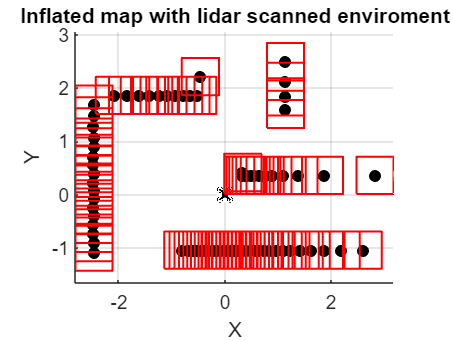

figure();
img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
imageWidth = 0.3; % Larghezza desiderata dell'immagine
imageHeight = 0.3; % Altezza desiderata dell'immagine
xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
yPos = 0 - imageHeight/2; % Posizionamento sull'asse y
hold on;
% Add the picture
image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
plot_obstacles(Drone.Drone_1.Lidar.scan_points_new ,Drone.Drone_1.Lidar.obstacles_lidar);
title('Inflated map with lidar scanned enviroment');
hold off;

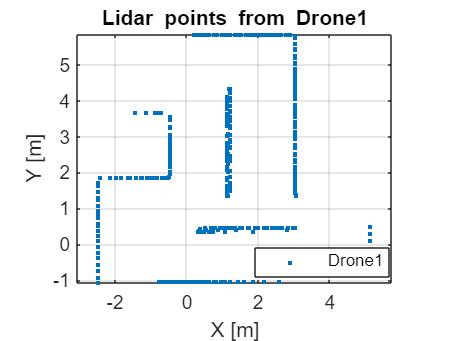

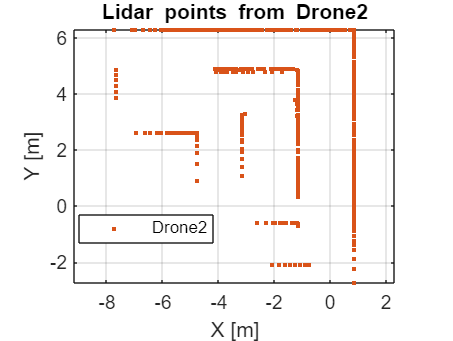

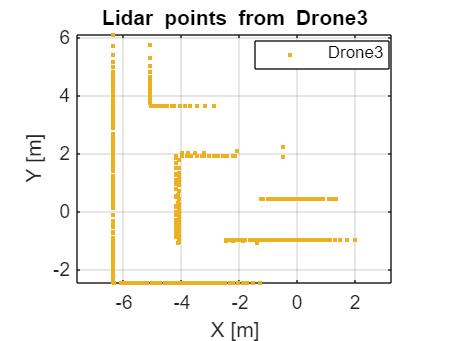

for i = 1:n
    figure();
    drone_name = ['Drone_' num2str(i)];
    plot(Drone.(drone_name).Lidar.scan_points(:,1) ,Drone.(drone_name).Lidar.scan_points(:,2), '.', 'Color', num2str(Drone.(drone_name).color));
    Droni= ['Drone{', num2str(i), '}'];
    axis equal;
    grid on;
    xlabel('X [m]');
    ylabel('Y [m]');
    legend(Droni,'Location', 'best');
    title(['Lidar points from Drone{', num2str(i), '}']);
end

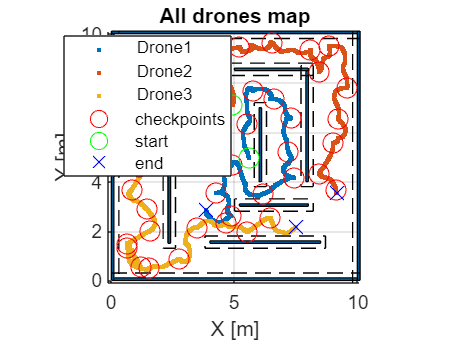

% Map plot where you see all the movements of the drones
figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('All drones map');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
hold on;

Droni = {};
for i = 1:n
    drone_name = ['Drone_' num2str(i)];
    plot(Drone.(drone_name).RRT.all_positions(:, 1), Drone.(drone_name).RRT.all_positions(:, 2), '.', 'Color', num2str(Drone.(drone_name).color));
    Droni{end+1} = ['Drone{', num2str(i), '}'];
end

for i = 1:n
    drone_name = ['Drone_' num2str(i)];
    plot(Drone.(drone_name).RRT.reached_goal(:, 1), Drone.(drone_name).RRT.reached_goal(:, 2),'ro','Markersize',10);
    plot(Drone.(drone_name).RRT.reached_goal(1, 1), Drone.(drone_name).RRT.reached_goal(1, 2),'go','Markersize',10);
    plot(Drone.(drone_name).RRT.all_positions(end, 1), Drone.(drone_name).RRT.all_positions(end, 2), 'bx','Markersize',10);
end
Droni{end+1} = 'checkpoints';
Droni{end+1} = 'start';
Droni{end+1} = 'end';
legend(Droni,'Location', 'best');

hold off;

# Return home Procedure

The coming home procedure is build in the following way

- Take the last scanned points and traslate in the position of the last simulation procedure

- Restart the RRT and PID controller to drive to meeting point all the drones (each goal point has to be referred to its own relative system)

- Build a flag vector to understand and stop the drones who reached the home goal

- Overlap all map point in the same final position

- (Generate the final obstacles map) ????????????????????????????????????

- Compare the original and reconstructed map

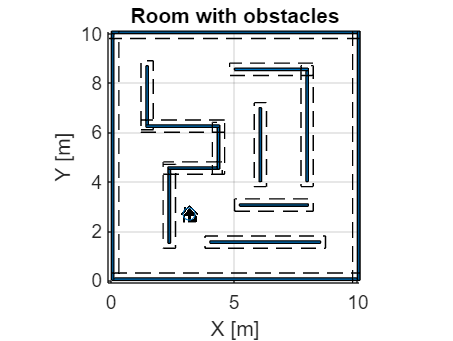

% Time of the coming home procedure
t = 0;
% Time steps of the procedure (in order to plot)
count_home  = count;
% Set the home position threshold
home_goal_threshold = 0.01;

% Set the home meeting point randomly absolute position

[~, inflated_obstacles_rrt] = inflated_rrt_map_definition(Drone.Drone_1.RRT.inflate); % change inflated map with the same limit of rrt

home_point = [rand() * x_map_size, rand() * y_map_size]; %[m]

while isInObstacle(home_point , inflated_obstacles_rrt) == true 
        % If the random starting point position is inside obstacles,
        % calculate another point
        home_point = [rand() * x_map_size, rand() * y_map_size];
end

%Plot the home position
figure();
img = imread('house.png'); % Sostituisci con il percorso dell'immagine
imageWidth = 0.7; % Larghezza desiderata dell'immagine
imageHeight = 0.7; % Altezza desiderata dell'immagine
xPos = home_point(1, 1) - imageWidth/2; % Posizionamento sull'asse x
yPos = home_point(1, 2) - imageHeight/2; % Posizionamento sull'asse y
hold on;
% Add the picture
image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);
plot(home_point(1, 1), home_point(1, 2), 'o');
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
hold off;

% Save in relative term the last total scanned points for each drone and
% the relative position of home goal
% INITIALIZATION RRT HOME
for i = 1:n
        
        % Recall the selected drone
        drone_name = ['Drone_' num2str(i)];
        
        % Find the lidar map that starts from the last previous simulation
        % instant
        Drone.(drone_name).Lidar.starting_coming_home_map =[Drone.(drone_name).Lidar.scan_points(:,1) - Drone.(drone_name).RRT.pos(1, 1), ...
            Drone.(drone_name).Lidar.scan_points(:,2) - Drone.(drone_name).RRT.pos(2, 1)];
        
        % Goal of the RRT in order to reach home goal position (in relative reference frame)
        Drone.(drone_name).RRT.home_point = home_point - Drone.(drone_name).RRT.all_positions(end, :); 

        %creating obstacles from scan
        Drone.(drone_name).Lidar.obstacles_lidar = lidar_data_to_obstacles(Drone.(drone_name).Lidar.starting_coming_home_map ,Drone.(drone_name).RRT.inflate);

        %creating rrt tree
        [Drone.(drone_name).RRT.rrt_tree, Drone.(drone_name).RRT.parent_indices] = RRT_DRONE(Drone.(drone_name).RRT.step_size, Drone.(drone_name).RRT.n_iterations, Drone.(drone_name).RRT.fov_drone,Drone.(drone_name).Lidar.starting_coming_home_map, Drone.(drone_name).RRT.inflate);
        Drone.(drone_name).RRT.farest = [0; 0];
        Drone.(drone_name).RRT.dist_farest = 0;
        for k=2:length(Drone.(drone_name).RRT.rrt_tree)
            Drone.(drone_name).RRT.temp_point = Drone.(drone_name).RRT.rrt_tree(k, :);
            if norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :)) > Drone.(drone_name).RRT.dist_farest
                Drone.(drone_name).RRT.dist_farest = norm(Drone.(drone_name).RRT.rrt_tree(1, :) - Drone.(drone_name).RRT.rrt_tree(k, :));
                Drone.(drone_name).RRT.farest = Drone.(drone_name).RRT.rrt_tree(k, :);
            end
        end
        Drone.(drone_name).RRT.correspondence = ismember(Drone.(drone_name).RRT.rrt_tree, Drone.(drone_name).RRT.farest, 'rows');
        Drone.(drone_name).RRT.index = find(all(Drone.(drone_name).RRT.correspondence, 2));
        Drone.(drone_name).RRT.points_rrt = [];
        while Drone.(drone_name).RRT.index ~= 0
            Drone.(drone_name).RRT.points_rrt = [Drone.(drone_name).RRT.rrt_tree(Drone.(drone_name).RRT.index, :); Drone.(drone_name).RRT.points_rrt];
            Drone.(drone_name).RRT.index = Drone.(drone_name).RRT.parent_indices(Drone.(drone_name).RRT.index);
        end
    
        %creating intermediates goals and final goal
        Drone.(drone_name).RRT.points = Drone.(drone_name).RRT.points_rrt';
        Drone.(drone_name).RRT.check_point_index = 2;
        Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:, Drone.(drone_name).RRT.check_point_index);

        % Initializing PID
    
        % Error variables
        Drone.(drone_name).PID.error_sum=0;
        Drone.(drone_name).PID.previous_error = 0;
    
        % Space and velocity variables
        Drone.(drone_name).RRT.initial_vel = [0; 0];
        Drone.(drone_name).RRT.positions = []; % position register
        Drone.(drone_name).RRT.reached_goal(1,1) = Drone.(drone_name).map(1,1);
        Drone.(drone_name).RRT.reached_goal(1,2) = Drone.(drone_name).map(1,2);
        Drone.(drone_name).RRT.all_positions_twhome = [Drone.(drone_name).map(1,1),Drone.(drone_name).map(1,2)]; % all pose momorized in abs terms
        
        Drone.(drone_name).RRT.pos = [0;0]; %Drone.(drone_name).RRT.points(:, 1);
        Drone.(drone_name).RRT.vel = Drone.(drone_name).PID.initial_vel;


end

Some plot to check the correct initialization

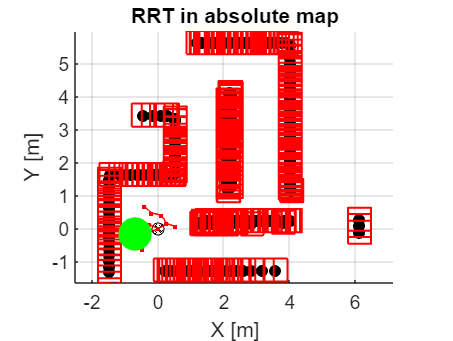

figure();
img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
imageWidth = 0.3; % Larghezza desiderata dell'immagine
imageHeight = 0.3; % Altezza desiderata dell'immagine
xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
yPos = 0 - imageHeight/2; % Posizionamento sull'asse y
hold on;
% Add the picture
image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
plot_obstacles(Drone.Drone_1.Lidar.starting_coming_home_map ,Drone.Drone_1.Lidar.obstacles_lidar);
title('Inflated map with lidar scanned enviroment');
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('RRT in absolute map');
hold on;
% PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
RRT_PLOT(Drone.Drone_1.RRT.rrt_tree, Drone.Drone_1.RRT.parent_indices);
plot(Drone.Drone_1.RRT.home_point(1, 1), Drone.Drone_1.RRT.home_point(1, 2), '.', 'MarkerSize', 50, 'Color', 'green');
hold off;

Run the simulation to come back to home, for each drone

% Flag to understand if they reached the meeting point
flag_end = zeros(1, n_droni);

% compute the coming home process untill all the drones reach the home
% Time flows until all the flags that tell about the reaching home point are triggered

while ~all(flag_end == 1)
    %t = t + SetUp.Dt;
    coun = count + 1;
      
    for i = 1:n
        drone_name = ['Drone_' num2str(i)];
        
        % PID control to move the drone
        % Check actual and target position to set up the controller
        Drone.(drone_name).PID.error_pos = Drone.(drone_name).RRT.final_pos - Drone.(drone_name).RRT.pos;
            
        % Proportional component
        Drone.(drone_name).PID.control_p = Drone.(drone_name).PID.Kp * Drone.(drone_name).PID.error_pos;

        % Integral component
        Drone.(drone_name).PID.error_sum = Drone.(drone_name).PID.error_sum + Drone.(drone_name).PID.error_pos * SetUp.Dt;
        Drone.(drone_name).PID.control_i = Drone.(drone_name).PID.Ki * Drone.(drone_name).PID.error_sum;

        % Derivative component
        Drone.(drone_name).PID.derivative = (Drone.(drone_name).PID.error_pos - Drone.(drone_name).PID.previous_error) / SetUp.Dt;
        Drone.(drone_name).PID.control_d = Drone.(drone_name).PID.Kd * Drone.(drone_name).PID.derivative;
        
        % Speed saturation
        Drone.(drone_name).PID.control_d = min(max(Drone.(drone_name).PID.control_d, -Drone.(drone_name).PID.max_speed), Drone.(drone_name).PID.max_speed);

        % Final limited acceleration control
        Drone.(drone_name).PID.control = Drone.(drone_name).PID.control_p + Drone.(drone_name).PID.control_i + Drone.(drone_name).PID.control_d;
        Drone.(drone_name).PID.control = min(max(Drone.(drone_name).PID.control, -Drone.(drone_name).PID.max_acc), Drone.(drone_name).PID.max_acc);
        
        % IMU noise added
        Drone.(drone_name).PID.control = Drone.(drone_name).PID.control + Drone.(drone_name).RRT.imu_noise * randn(2, 1);

        % Speed and position update
        Drone.(drone_name).RRT.vel = Drone.(drone_name).RRT.vel + Drone.(drone_name).PID.control * SetUp.Dt;
        Drone.(drone_name).RRT.pos = Drone.(drone_name).RRT.pos + Drone.(drone_name).RRT.vel * SetUp.Dt;

        % Pose memorization
        Drone.(drone_name).RRT.positions = [Drone.(drone_name).RRT.positions, Drone.(drone_name).RRT.pos];
        
        Drone.(drone_name).RRT.reached_goal(count,1) = Drone.(drone_name).map(Drone.(drone_name).count_pos,1);
        Drone.(drone_name).RRT.reached_goal(count,2) = Drone.(drone_name).map(Drone.(drone_name).count_pos,2); 
        Drone.(drone_name).RRT.all_positions(count,1) = Drone.(drone_name).RRT.reached_goal(count,1) + Drone.(drone_name).RRT.pos(1,1);
        Drone.(drone_name).RRT.all_positions(count,2) = Drone.(drone_name).RRT.reached_goal(count,2) + Drone.(drone_name).RRT.pos(2,1);
        
        % Error update
        Drone.(drone_name).PID.previous_error = Drone.(drone_name).PID.error_pos;
        % ______________________________________
        % From now on a series of if to check and control the planning
        % steps of the drone in the RRT exploration point IFF it has not
        % reached the home goal yet
        
        %  Check if a general intermediate checkpoint position of the RRT tree is reached 
        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.final_pos) <= proximity_threshold && Drone.(drone_name).RRT.check_point_index < length(Drone.(drone_name).RRT.points) ...
                && flag_end (1, n) == 0
            % aggiungere punto check point approx
            Drone.(drone_name).RRT.check_point_index = Drone.(drone_name).RRT.check_point_index +1;
            Drone.(drone_name).RRT.final_pos = Drone.(drone_name).RRT.points(:,Drone.(drone_name).RRT.check_point_index); 

        end

        % Check if the final point if the local RRT tree is reached
        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.points(:,length(Drone.(drone_name).RRT.points))) <= proximity_threshold ...
               && flag_end (1, n) == 0
            
            % Update of position index saved in the map
            Drone.(drone_name).count_pos = Drone.(drone_name).count_pos +1; 

            % Save the reached position in relative terms and use it in the
            % following RRT as the new starting point in the successive in
            % map variable
            Drone.(drone_name).map(Drone.(drone_name).count_pos,1) = Drone.(drone_name).map(Drone.(drone_name).count_pos-1,1) +  Drone.(drone_name).RRT.pos(1,1); %pos x abs
            Drone.(drone_name).map(Drone.(drone_name).count_pos,2) = Drone.(drone_name).map(Drone.(drone_name).count_pos-1,2) +  Drone.(drone_name).RRT.pos(2,1); %pos y abs
            Drone.(drone_name).map_rel(Drone.(drone_name).count_pos,1) = Drone.(drone_name).RRT.pos(1,1); %pos x rel
            Drone.(drone_name).map_rel(Drone.(drone_name).count_pos,2) = Drone.(drone_name).RRT.pos(2,1); %pos y rel
           
            % Save last speed of the drone in order to use it as the new
            % Starting velocity in the next RRT plannig step
            Drone.(drone_name).RRT.final_velocity = Drone.(drone_name).RRT.vel;

            % New scan in the reached point in order to generate the new RRT 
            [~,~, Drone.(drone_name).Lidar.scan_points_new, Drone.(drone_name).Lidar.scan_dist_new] = Lidar_scan(obstacles, Drone.(drone_name).map(Drone.(drone_name).count_pos,:), Drone.(drone_name).Lidar.lidar_angles, Drone.(drone_name).Lidar.max_range, Drone.(drone_name).Lidar.lidar_dist_res);
            
            % Fuse previous lidar points of the old map in the new just created
            map1 = Drone.(drone_name).Lidar.scan_points; % Old point clouds of drone n
            map2 = Drone.(drone_name).Lidar.scan_points_new; % New point cloud  drone n dto be fused
            pos1 = Drone.(drone_name).map(Drone.(drone_name).count_pos-1,:); % Old ground truth pose drone n
            pos2 = Drone.(drone_name).map(Drone.(drone_name).count_pos,:); % New (current) ground truth posizione drone n 
            
            % Virtual traslation (overlay) of old map (map1) on new reached point on new scanned map (map2)
            virtual_points = [map1(:,1)-Drone.(drone_name).RRT.pos(1,1),map1(:,2)-Drone.(drone_name).RRT.pos(2,1)];
            
            % Define the common points that theoretically are the same betweeen old and new scan
            soglia = 0.1;
            common_points = point_cloud_compare(virtual_points,map2,soglia);
            
            % Generate the new cumulated scanned point maps
            new_map2 = fused_map(virtual_points, common_points, map2, drone_name);

            % Initialization and saving new meshed map in the scan_points_field
            Drone.(drone_name).Lidar.scan_points = [0,0];
            Drone.(drone_name).Lidar.scan_points = new_map2;
        end


        if norm(Drone.(drone_name).RRT.pos - Drone.(drone_name).RRT.home_point) <= proximity_threshold ...
               && flag_end (1, n) == 0
            % Change the value of the flag in order to comunicate that the
            % drone has reached the home and to block in its position
            flag_end (1, n) = 1;
            % Initialize the pid to stop the drone
            Drone.(drone_name).PID.error_sum=0;
            Drone.(drone_name).PID.previous_error = 0;
        
            % Space and velocity variables
            Drone.(drone_name).RRT.initial_vel = [0; 0];
            Drone.(drone_name).RRT.positions = []; % position register
            Drone.(drone_name).RRT.pos = [0;0]; %Drone.(drone_name).RRT.points(:, 1);
            Drone.(drone_name).RRT.vel = Drone.(drone_name).PID.initial_vel;
        end
        

    
    % fare scan all'ultima posizione per ogni drone
    % fondere scan con mappa totale riferito a se
    % overlappo tutti

    end
end

Error using intersect>intersectR2012a
Inputs A and B must have the same number of columns in the 'rows' case.

Error in intersect (line 165)
        [varargout{1:nlhs}] = intersectR2012a(varargin{1:2},logical(flaginds(1:3)));

Error in combine_point_clouds (





%------------------------------------------------------------------- end of all simulation ----------------------------------------------------------------

#### Map lidar scan to undestand the surroundings

% % start = [rand() * x_map_size, rand() * y_map_size]; % absolute poi from wich the drone starts the simulation
% % 
% %  while isInObstacle(start, inflated_obstacles)   % if the drone is shipped into a wall, selcet a new possible point until it is a good hit
% %         start = [rand() * x_map_size, rand() * y_map_size];
% %  end
% 
% % For now test with a given point
% start = [5, 8]; % absolute poi from wich the drone starts the simulation
% 
% lidar_position = start;
% lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
% max_range = 2;
% lidar_dist_res = 0.01; 
% [point_abs,point_abs_clean, point_rel, dist_rel] = Lidar_scan(obstacles, lidar_position, lidar_angles, max_range, lidar_dist_res);
% 
% 
% % Plot LiDAR result in relative envioment
% plot(point_rel(:, 1), point_rel(:, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black', 'MarkerSize', 5); % Plot ray
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% title('Lidar Relative point position');
% 
% 
% img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
% imageWidth = 0.5; % Larghezza desiderata dell'immagine
% imageHeight = 0.5; % Altezza desiderata dell'immagine
% xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
% yPos = 0 - imageHeight/2; % Posizionamento sull'asse y
% 
% % Aggiungi l'immagine alla posizione specificata
% image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);
% 

#### Plot the RRT

% figure();
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% %xlim([-0.10 x_map_size + 0.1]);
% %ylim([-0.10 y_map_size + 0.1]);
% title('RRT in relative map');
% hold on;
% PLOT_MAP(obstacles_lidar, inflated_obstacles_lidar, 10, 10);
% RRT_PLOT(rrt_tree, parent_indices);
% hold off;
% 
% % Da plottare in sistema assoluto?
% figure();
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% title('RRT in absolute map');
% hold on;
% PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
% RRT_PLOT(rrt_abs_tree, parent_indices);
% hold off;

% % Visualizzazione del percorso
% %starting point in red
% plot(positions(1, 1), positions(2, 1), 'o', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'black', 'DisplayName','Starting point');
% %plot the path
% plot(positions(1, :), positions(2, :), '.', 'Color', 'black', 'DisplayName','Instantaneous position');
% %ending point in black
% 
% 
% xlabel('X [m]');
% ylabel('Y [m]');
% title('PID test track');
% legend('Location','bestoutside');
% hold off
% 
% 

% % plot all in the absolute ref frame
% figure();
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% xlim([-0.10 x_map_size + 0.1]);
% ylim([-0.10 y_map_size + 0.1]);
% title('PID control result');
% PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
% hold on;
% RRT_PLOT(rrt_abs_tree, parent_indices);
% plot(positions(1, 1) + start(1, 1) , positions(2, 1) + start(1, 2), 'o', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'black');
% plot(positions(1, length(positions)) + start(1, 1), positions(2, length(positions)) + start(1, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black');
% plot(positions(1, :) + start(1, 1), positions(2, :) + start(1, 2), '.', 'Color', 'black');
% hold off;
% 

elapsed_time_simulation = toc; % stop measuring time
fprintf( 'Simulation completed\n' )
fprintf( 'The total simulation time was %.2f seconds\n', ...
         elapsed_time_simulation)
